# Channel Estimation OFDM

The provided MATLAB code simulates a basic communication system using OFDM modulation. The simulation involves the generation of a payload data, modulation of data, transmission over a channel, and the estimation of the channel's response.

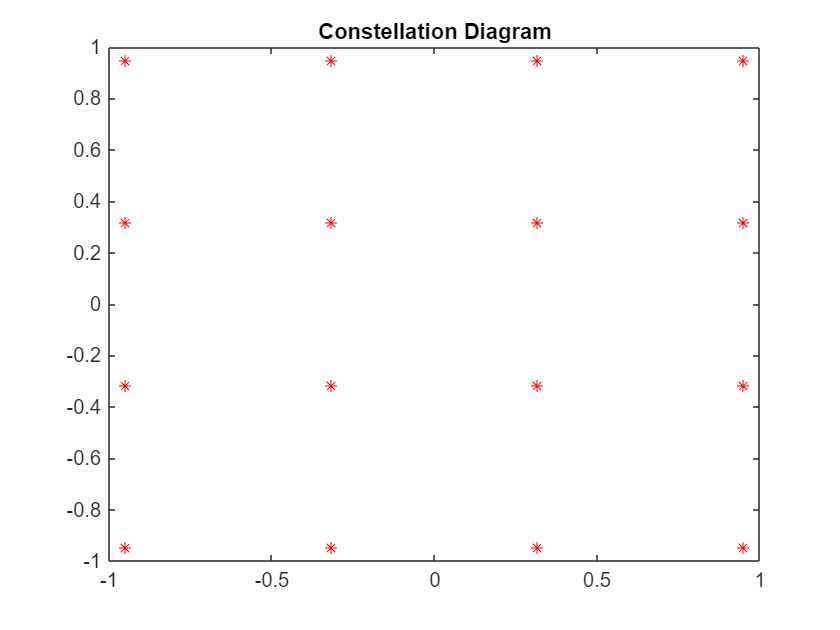

clear variables;

bps = 4;    % Bits per symbol
M = 2^bps;  % 16QAM
n_FFT = 1024; % Number of FFT bins
n_SCoccupied = 601; % Number of occupied subcarriers
n_CP = 72;    % CP length

% Loop over different SNR values
SNRdB_vec = -5:5:40; % SNR values to loop over
nSymbols = 35; % Number of simulations for each SNR value

% Bit stream generation and modulation
txdata = randi([0 1],n_SCoccupied*bps*nSymbols,1);
txsymbols = qammod(txdata,M,UnitAveragePower=true,InputType="bit"); % apply qammod

% Reshape to txgrid
txgrid = reshape(txsymbols,n_SCoccupied,nSymbols);

% Observe the constellation diagram
figure; 
plot(txgrid,'*r')
title('Constellation Diagram');

**Pilot Sequence Generation and Insertion**

Consider a Comb-type pilot pattern, i.e. At pilot subcarriers of every symbol there is a reference signal. Write the code for the following steps:

- Pilot sequence generation: write a code in order to create a vector of pilot-subcarriers. The same vector can be repeated for every OFDM symbol (Comb-Type).

- With a modification in the Tx data grid, consider reserving pilot-subcarriers for pilots, i.e. avoid data transmission on those subcarriers, and correspondingly insert the pilots.

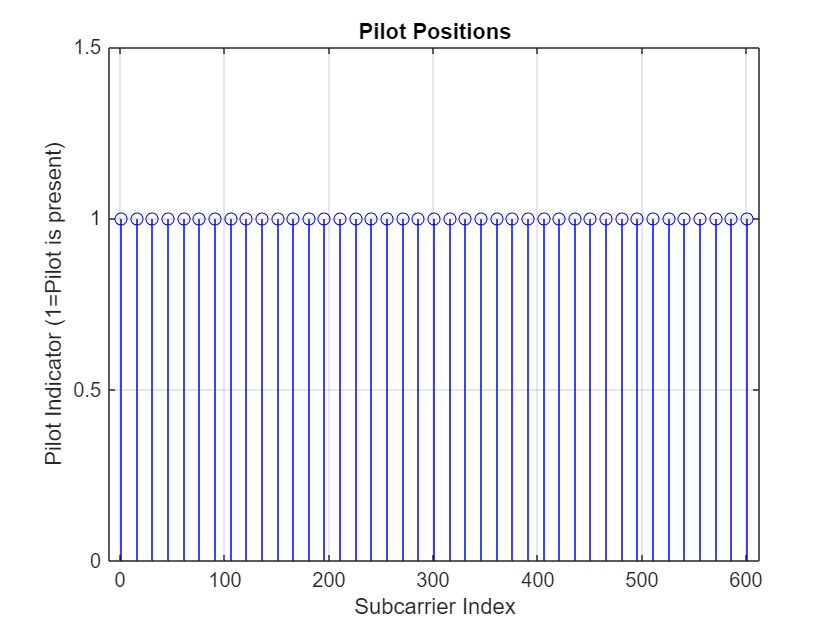

%Pilot parameters
pilotSpacing = 15 ;
pilotValue = 1-1j ;

%Pilot creation & generation
pilotIndex =1:pilotSpacing:n_SCoccupied ;
txgridWithPilots = txgrid ;
txgridWithPilots(pilotIndex, :) = pilotValue;

%Visualized Pilot positions
figure;
stem(pilotIndex,ones(size(pilotIndex)) , 'b' ,'LineWidth', 0.5) ;
title ('Pilot Positions') ;
xlabel ('Subcarrier Index')
ylabel ('Pilot Indicator (1=Pilot is present)');
ylim([0 , 1.5]);
grid on

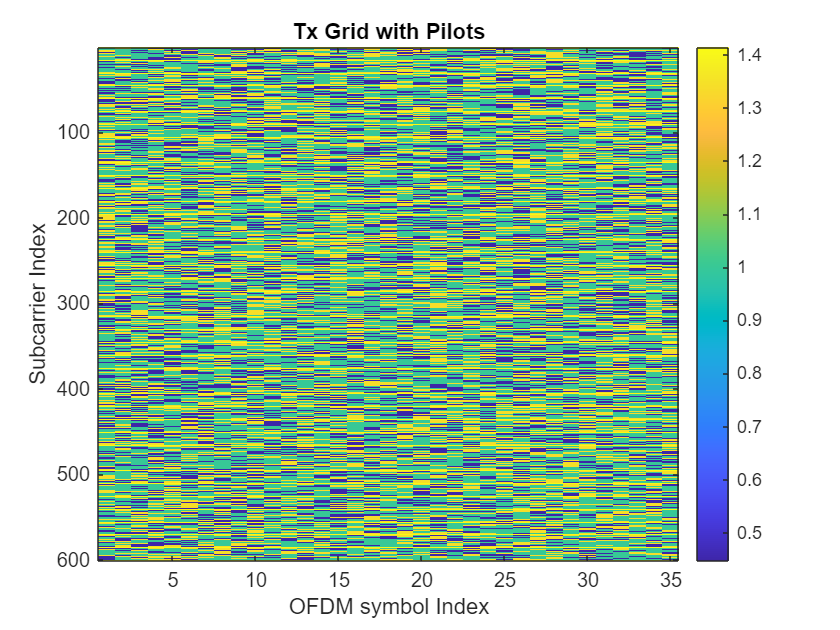

%Visualized the transmit grid with pilots

figure;
imagesc(abs(txgridWithPilots));
title('Tx Grid with Pilots');
xlabel('OFDM symbol Index');
ylabel('Subcarrier Index');
colorbar;

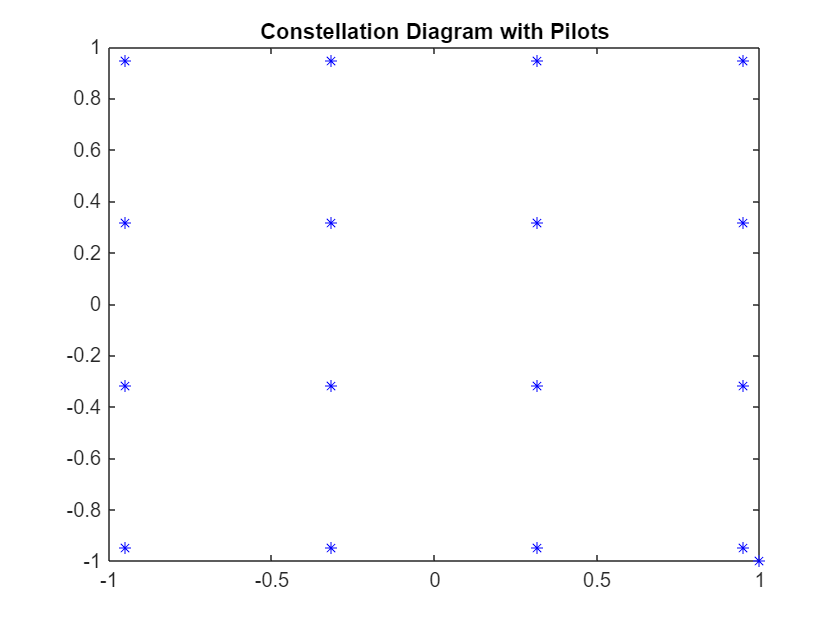


%Observe the Constellation diagram
figure;
plot(txgridWithPilots,'*b')
title('Constellation Diagram with Pilots');

**Virtual Subcarrier Insertion**

The guard subcarriers play a critical role in maintaining the integrity and performance of OFDM systems by guarding against both time-domain and frequency-domain distortions, ultimately improving the system's resilience to various channel impairments.

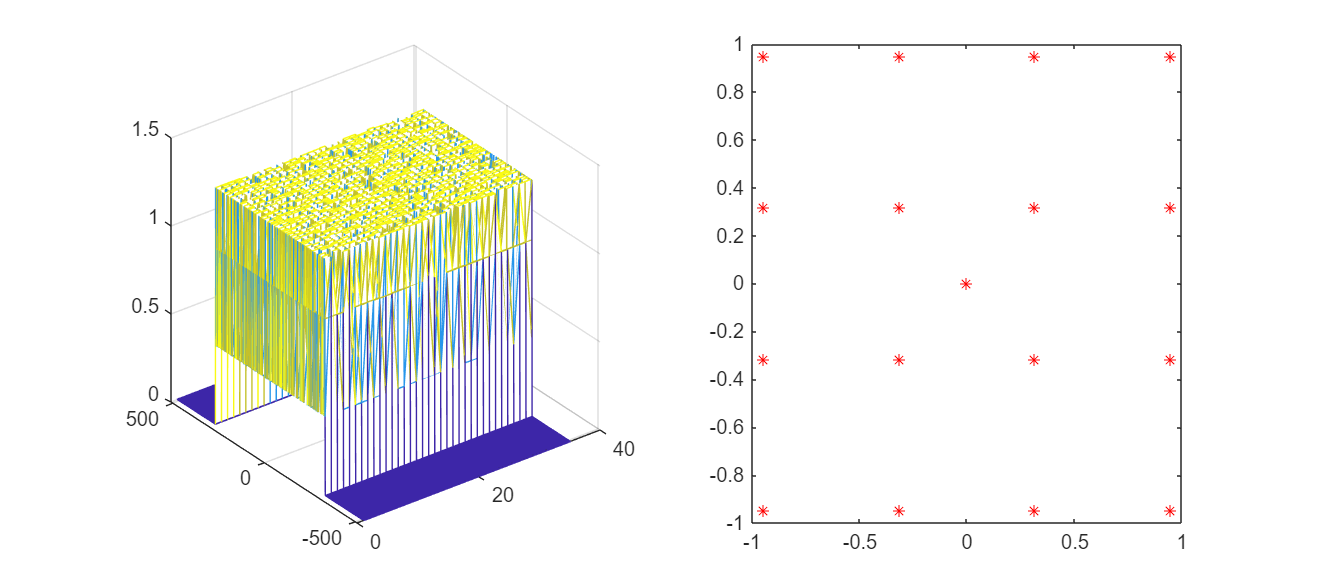

% Insert Guard subcarriers
txgrid_withGB = insertGaurdSubcarriers(txgrid,n_SCoccupied,n_FFT);    

% Observe the IFFT Input
figure('Position',[0 0 900 400]); 
subplot(1,2,1);
mesh(1:nSymbols,-n_FFT/2:n_FFT/2-1,abs(txgrid_withGB));
subplot(1,2,2);
plot(txgrid_withGB,'*r')

**Create a Time-Domain Signal**

% Apply IFFT
txgrid_inTime = ifft(txgrid_withGB);

**Add Cyclic Prefix**

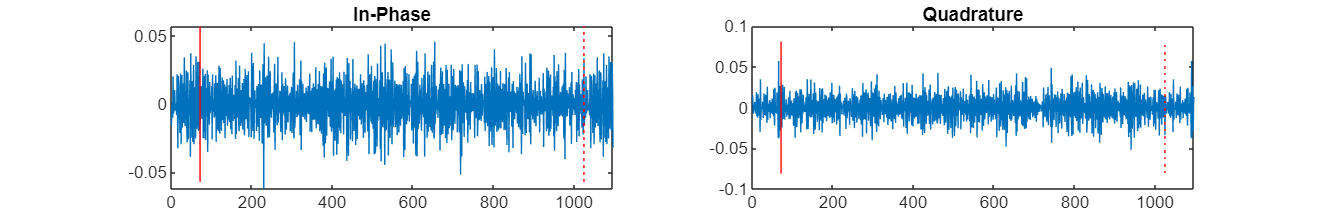

addCP = true;
if addCP
    % add a cyclic prefix for tx
    txgrid_withCP = insertCP(txgrid_inTime,n_CP);    

    % Observe the result on a random signal
    figure('Position',[0 0 2500 400]); 
    subplot(1,2,1)
    plot(real(txgrid_withCP(:,randi(nSymbols))))
    peakval1 = max(abs(real(txgrid_withCP(:,randi(nSymbols)))));
    hold on; plot([n_CP n_CP],[-peakval1 peakval1],'r'); plot([n_FFT n_FFT],[-peakval1 peakval1],':r')   
    title('In-Phase')
    xlim([0 n_FFT+n_CP]);
    subplot(1,2,2)
    plot(imag(txgrid_withCP(:,randi(nSymbols))))
    peakval2 = max(abs(imag(txgrid_withCP(:,randi(nSymbols)))));
    hold on; plot([n_CP n_CP],[-peakval2 peakval2],'r'); plot([n_FFT n_FFT],[-peakval2 peakval2],':r')    
    title('Quadrature')
    xlim([0 n_FFT+n_CP]);
else
    txgrid_withCP = txgrid_inTime;
end

% Vectorize the OFDM symbols in form of a single time domain signal
txout = txgrid_withCP(:);

**Channel Multipath**

Define the channel parameters and then filter the transmit signal through the channel.

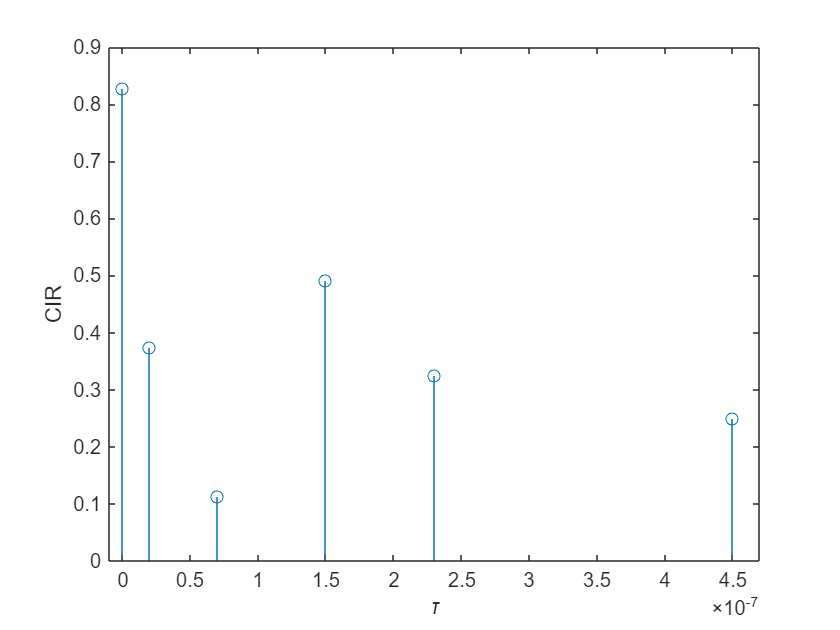

% Doppler frequency
v = 0.001;                                      % UE velocity in km/h
fc = 1.8e9;                                     % carrier frequency in Hz
fs = 15.46e6;                                   % Sampling rate
c = physconst('lightspeed');                    % speed of light in m/s
maxDopplerShift = (v/3.6)/(c/fc);               % UE max Doppler frequency in Hz

% Multipath channel parameters
delayVector1 = [0 20 70 150 230 450]*1e-9;  % discrete delays for 6 path fading channel in s
gainVector1 = [0 -1 -2 -3 -6 -9];            % average path gains in dB

chan_obj = comm.RayleighChannel('SampleRate',fs,...
                        'PathDelays',delayVector1, ...
                        'AveragePathGains',gainVector1,...
                        'MaximumDopplerShift',maxDopplerShift,...
                        'PathGainsOutputPort',1);

% Send a pure tone to find the CIR filter coefficients
[ch_puretone, pathGains] = chan_obj([complex(1,0); zeros(n_CP,1)]);

% Observe the true CIR
figure; 
stem(delayVector1, abs(pathGains(1,:)))
ylabel('CIR'); xlabel('\tau')
xlim([-1e-8 470e-9])

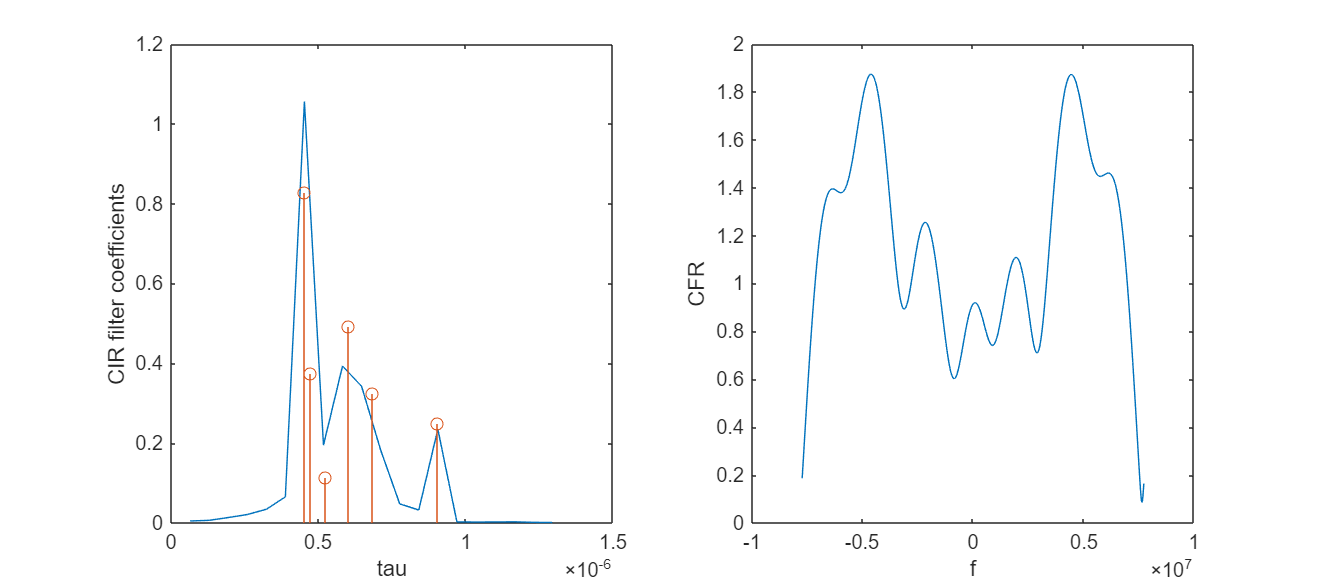


% Observe the CIR filter coefficients and CFR that the pure tone experiences
figure('Position',[0 0 900 400]);
chan_filter_synced = circshift(ch_puretone,-1); % Synchronization
chan_filter_ZeroPadded = [chan_filter_synced(1:40); zeros(1024-n_CP-1,1); chan_filter_synced(41:end)];

subplot(1,2,1)
plot((1:20)/fs,abs(chan_filter_ZeroPadded(1:20)))
ylabel('CIR filter coefficients')
xlabel('tau')
hold on; stem(delayVector1+7/fs, abs(pathGains(1,:)))

subplot(1,2,2)
plot(linspace(-fs/2,fs/2,n_FFT),abs(fft(chan_filter_ZeroPadded)))
ylabel('CFR')
xlabel('f')


% Apply the channel to the transmit signal
[chwaveform, pathGains] = chan_obj(txout);

**Perfect Channel Estimation**

Apply perfect channel estimation knowing the characteristics of the communication channel through which the signal travels. 

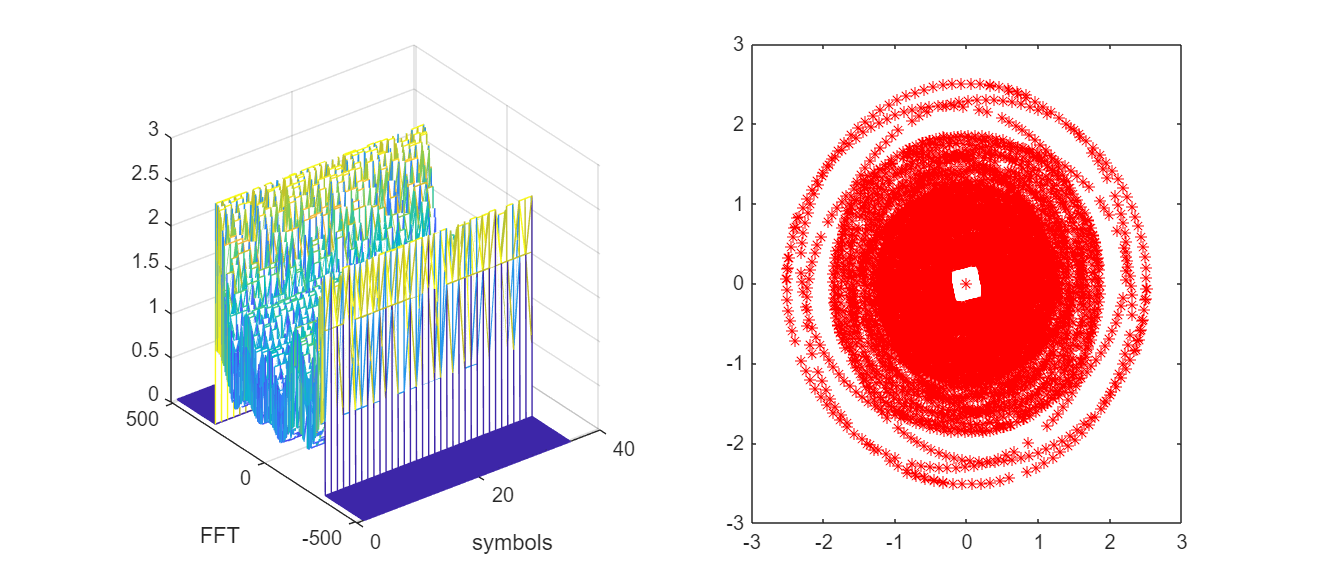

% Reshape the receive signal
chwaveform_withCP = reshape(chwaveform, [n_FFT+n_CP nSymbols]);

% Remove the CP
chwaveform_noCP = removeCP(chwaveform_withCP,n_CP);

% OFDM Demodulation (apply FFT)
rxgrid_withGB = fft(chwaveform_noCP);

% Observe the receive signal grid
figure('Position',[0 0 900 400]);
subplot(1,2,1)
mesh(1:nSymbols,-n_FFT/2:n_FFT/2-1,abs(rxgrid_withGB));
xlabel('symbols');
ylabel('FFT');
subplot(1,2,2);
plot(rxgrid_withGB,'*r')

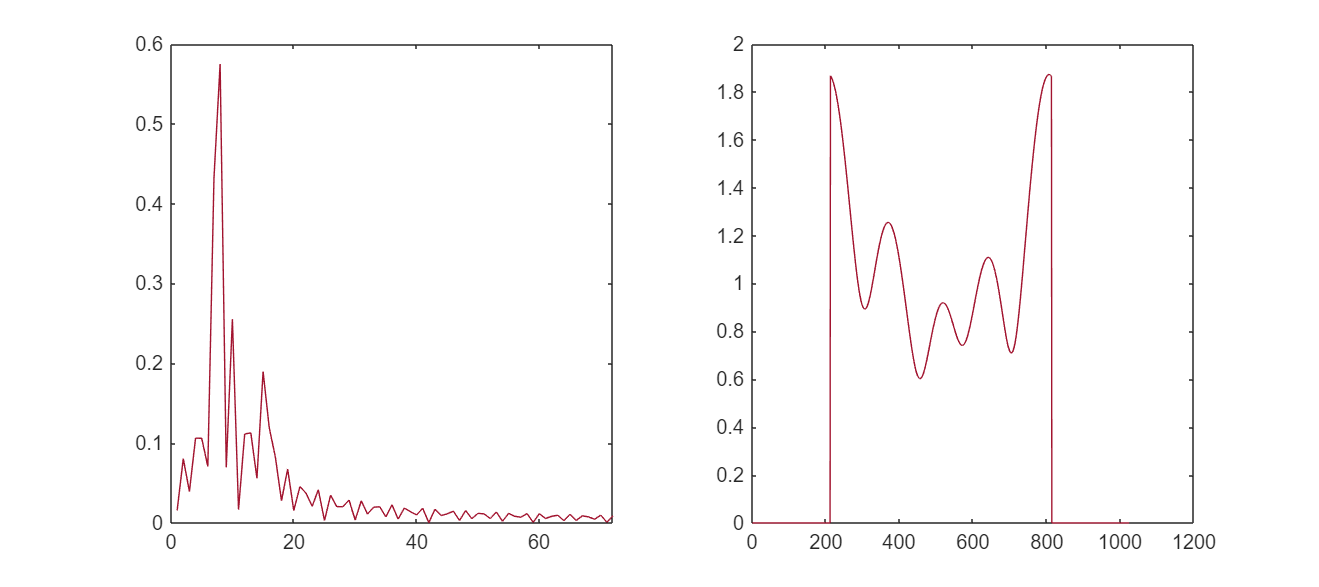

% Remove Guardbands
rxgrid = removeGaurdSubcarriers(rxgrid_withGB,n_SCoccupied,n_FFT);

% Apply Least Squares channel estimation on noiseless symbols
Hhat_perfect = rxgrid./txgrid;

Hhat_perfect_withGB = insertGaurdSubcarriers(Hhat_perfect,n_SCoccupied,n_FFT);

% Observe the channel response
figure('Position',[0 0 900 400]);
subplot(1,2,1)
plot(abs(ifft(Hhat_perfect_withGB)))
xlim([0 n_CP])

subplot(1,2,2) 
plot(abs(Hhat_perfect_withGB));

**Pilot-based channel estimation**

Channel estimation based on reference signals

- Extract the pilot signals

- Estimate the channel at pilot subcarriers by considering the two case: I) Noiseless channel, II) Over AWGN

- Interpolate the channel for data subcarriers

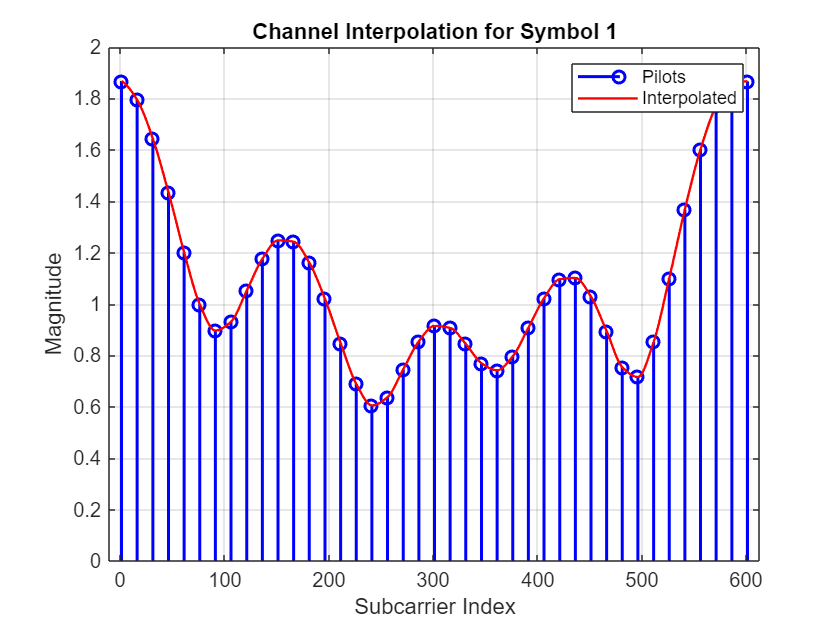

% Rx & Tx Pilot subcarriers 
rxPilots = rxgrid(pilotIndex, :);        % Rx pilot subcarriers
txPilots = txgrid(pilotIndex, :);        % Tx pilot subcarriers

% LS Estimation at pilot subcarriers
H_pilots = rxPilots ./ txPilots;

symbolIndex = 1;
H_pilots_symbol = H_pilots(:, symbolIndex);

% Sort pilots
[pilotPosSorted, sortIdx] = sort(pilotIndex(:));
H_pilots_sorted = H_pilots(sortIdx, :);

% Interpolating wrt magnitude smoothly using pchip algorithm
fullPos = (1:n_SCoccupied).';
Hmag_interp = interp1(pilotPosSorted, abs(H_pilots_sorted), fullPos, 'pchip', 'extrap');
Hmag_interp = max(Hmag_interp, min(abs(H_pilots_sorted)));  

%interplolated channel magnitude 
Hhat_estimated = Hmag_interp;

Hhat_estimated_symbol = Hhat_estimated(:, symbolIndex);

% Plot
figure;
stem(pilotIndex, abs(H_pilots_symbol), 'b', 'LineWidth', 1.5); 
hold on;
plot(1:n_SCoccupied, abs(Hhat_estimated_symbol), '-r', 'LineWidth', 1.2);
xlabel('Subcarrier Index'); ylabel('Magnitude');
title(['Channel Interpolation for Symbol ', num2str(symbolIndex)]);
legend('Pilots', 'Interpolated');
grid on;

**Simulation**

Simulation of a static channel through AWGN for various SNR values. Correspondingly, equalizing the receive signal. 

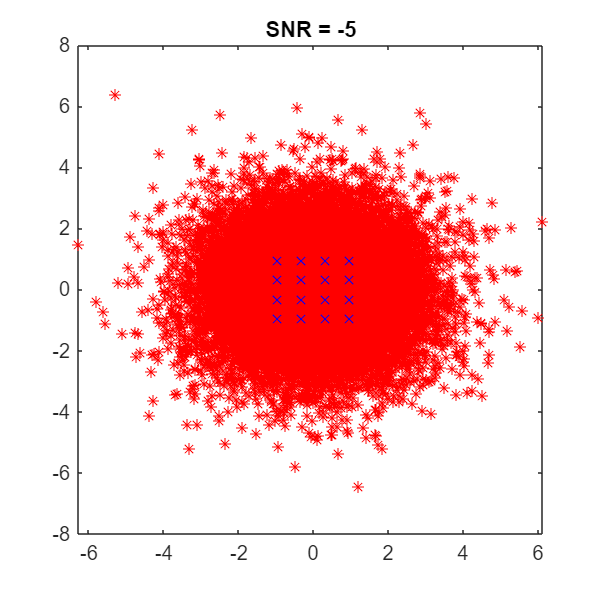

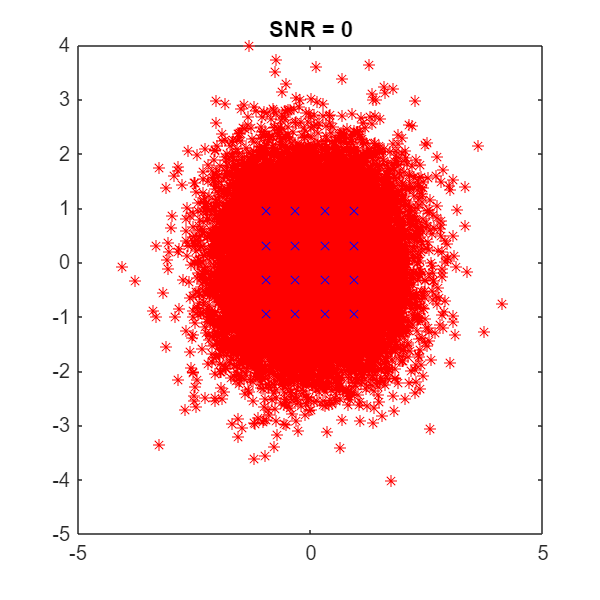

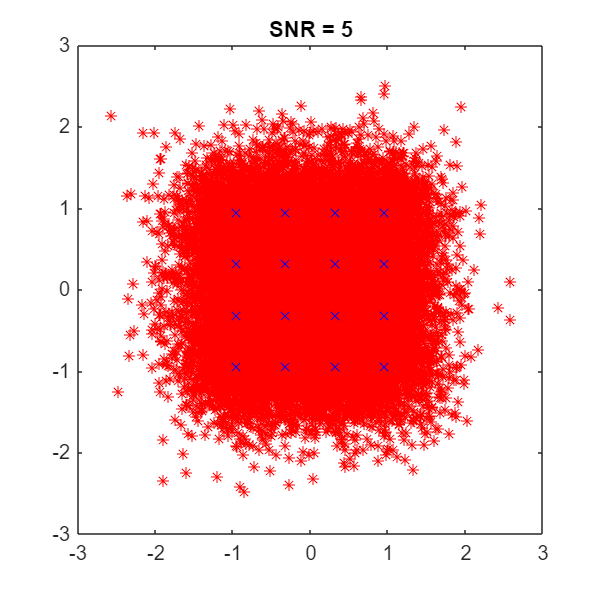

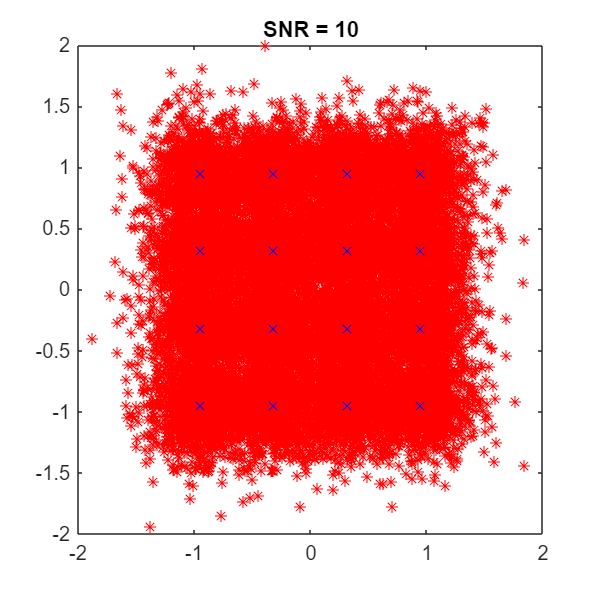

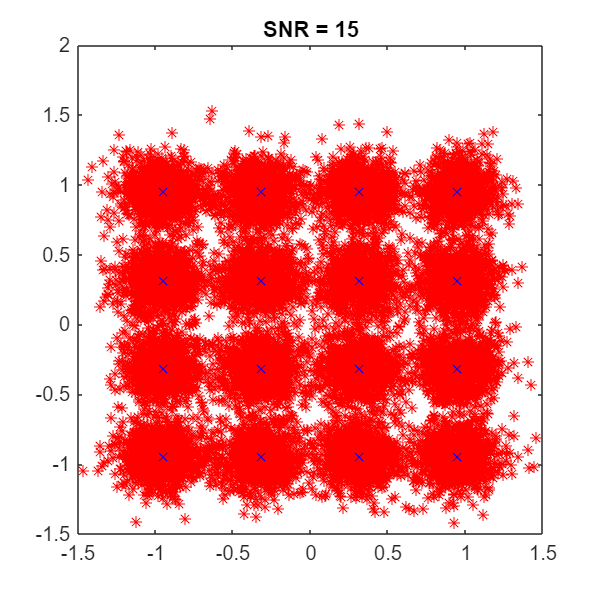

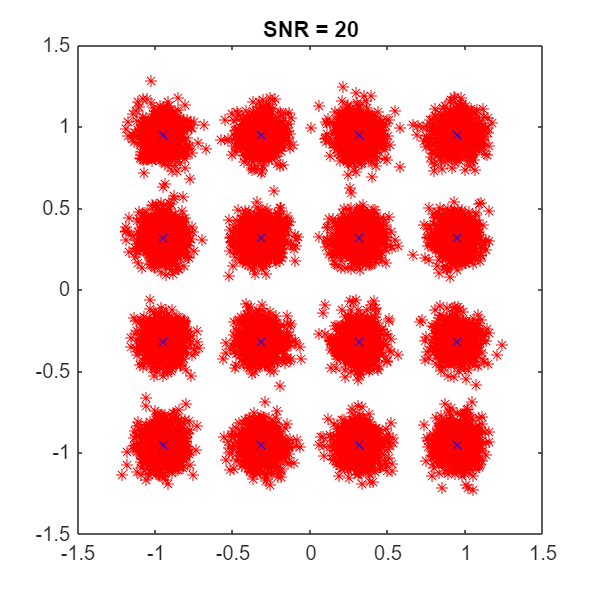

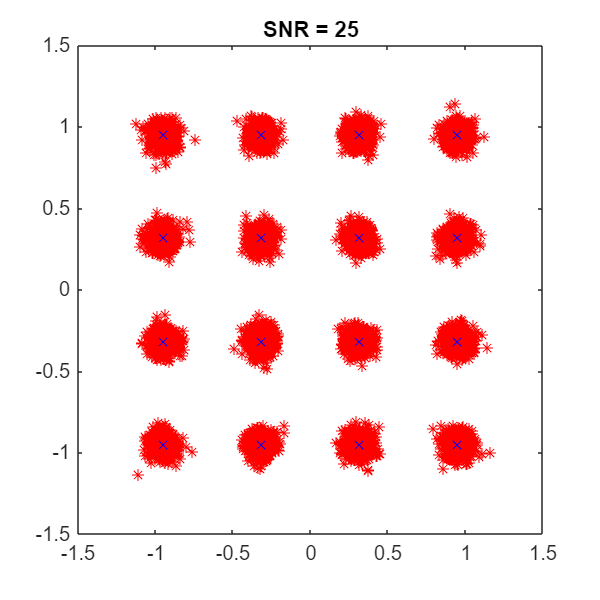

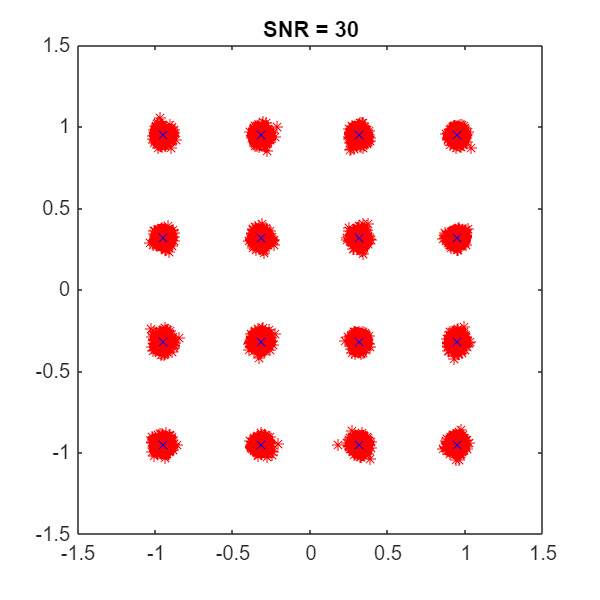

totalBER = [];

for SNRdB = SNRdB_vec
        % Additive white Gaussian noise
        chwaveform_in = awgn(chwaveform,SNRdB,"measured"); 

        % Reshape the receive signal
        chwaveform_withCP = reshape(chwaveform_in, [n_FFT+n_CP nSymbols]);

        % Remove the CP
        chwaveform_noCP = removeCP(chwaveform_withCP,n_CP);
        
        % OFDM Demodulation (apply FFT)
        rxgrid_withGB = fft(chwaveform_noCP);        

        % Remove Guardbands
        rxgrid = removeGaurdSubcarriers(rxgrid_withGB,n_SCoccupied,n_FFT);

        ApplyEqualizationPE = true;
        if ApplyEqualizationPE
            rxgridEQ = rxgrid./Hhat_perfect;
        else
            rxgridEQ = rxgrid./Hhat_estimated;
        end

        % Observe the equalized constellations and compare them with the Tx data 
        plotEQconstellation = true;
        if plotEQconstellation
            figure('Position',[0 0 400 400]);
            plot(rxgridEQ,'*r'); % * shapes with red color
            hold on;
            plot(txgrid, 'xb'); % x shapes with blue color
            SNR_str = sprintf("SNR = %d", SNRdB);
            title(SNR_str);
        end

        % apply qammod, with average power of the transmitted signal is normalized to 1
        rxdata = qamdemod(rxgridEQ,M,UnitAveragePower=true,OutputType="bit");         
        rxdata = rxdata(:);

        errors = sum(txdata ~= rxdata);
        BER = errors / (n_SCoccupied*bps*nSymbols);

        % Calculate average BER for this SNR
        totalBER = [totalBER BER];
end

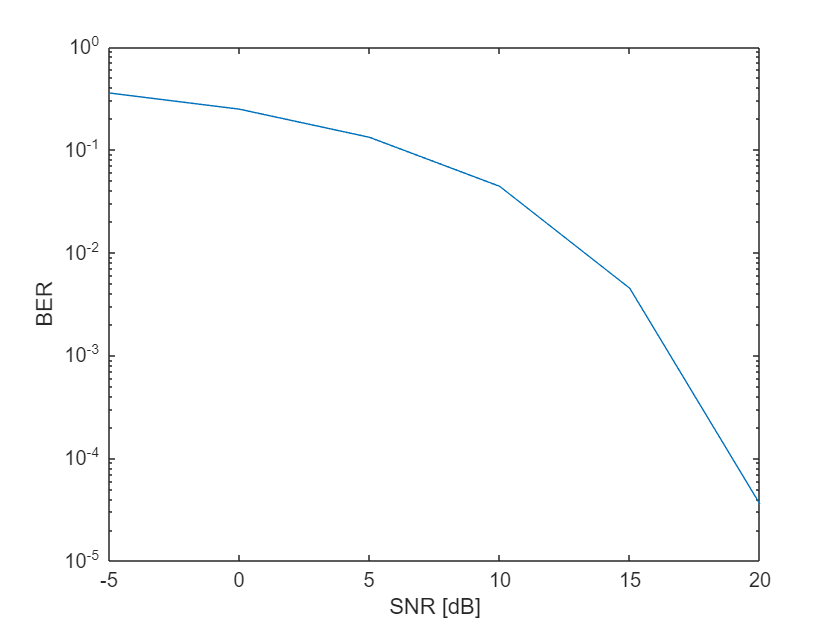

figure;
semilogy(SNRdB_vec, totalBER);
xlabel('SNR [dB]');
ylabel('BER')

**Functions**

function [txgrid] = insertGaurdSubcarriers(txsymbols,n_occupied,nFFT) % Guard bands
    GuardCarriers_left = zeros(ceil((nFFT-n_occupied)/2), size(txsymbols,2)); 
    GuardCarriers_right = zeros(floor((nFFT-n_occupied)/2), size(txsymbols,2)); 
    txgrid = [GuardCarriers_left; txsymbols; GuardCarriers_right];
end

function [rxsymbols] = removeGaurdSubcarriers(rxgrid,n_occupied,nFFT)
    rxsymbols = rxgrid(ceil((nFFT-n_occupied)/2)+1:end-floor((nFFT-n_occupied)/2),:);
end

function txout = insertCP(tx_signal,nCP)
    txout = [tx_signal(end-nCP+1:end,:); tx_signal];
end

function rxgrid_inTime = removeCP(rxgrid_withCP,nCP)
    rxgrid_inTime = rxgrid_withCP(nCP+1:end,:);
end
